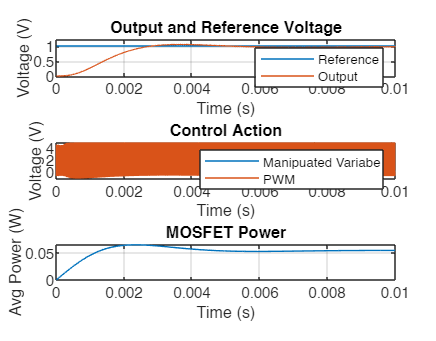

% Assuming SDOSimTest_Log.Vout.Data is the length you want for the vector
vector_length = length(SDOSimTest_Log.Vout.Data);
% Creating a vector of ones with the specified length
ones_vector = ones(1, vector_length);

figure
subplot(3,1,1)
plot(SDOSimTest_Log.Vout.Time,ones_vector); hold on
plot(SDOSimTest_Log.Vout.Time,SDOSimTest_Log.Vout.Data); hold off
title('Output and Reference Voltage')
legend('Reference','Output')
xlabel('Time (s)')
ylim([0,1.2])
ylabel('Voltage (V)')
grid on

subplot(3,1,2)
plot(SDOSimTest_Log.control_action.Time,SDOSimTest_Log.control_action.Data); hold on
plot(SDOSimTest_Log.PWM.Time,SDOSimTest_Log.PWM.Data); hold off
title('Control Action')
legend('Manipuated Variabe','PWM')
xlabel('Time (s)')
ylabel('Voltage (V)')
grid on

subplot(3,1,3)
plot(SDOSimTest_Log.power_mosfet.Time,SDOSimTest_Log.power_mosfet.Data)
title('MOSFET Power')
xlabel('Time (s)')
ylabel('Avg Power (W)')
grid on 